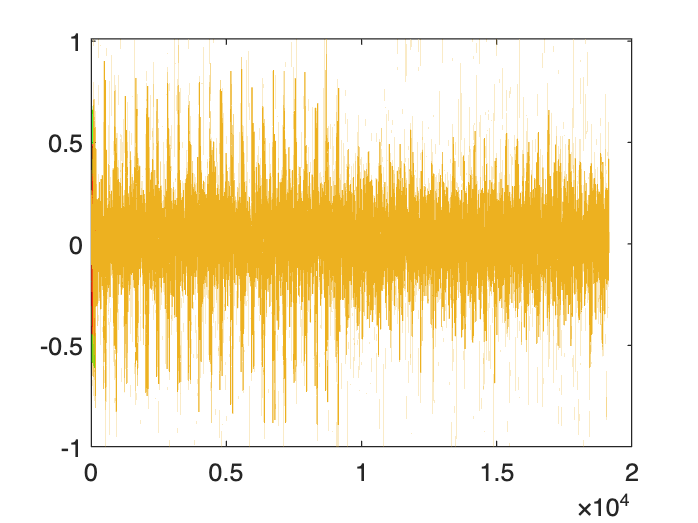

load("Evoked Potential.mat")

% number of evoked potentials 
M = 10;

% i select only the first M triggers
trigger_reduced = trigger(1:M);

% Calcola il potenzia\le evocato ideale utilizzando solo i primi M evoked potentials
ie_p_reduced = mean(ie_p(:, 1:M), 2);

% Chiama la funzione corrente utilizzando i nuovi trigger e il nuovo potenziale evocato ideale
[s_a, c_avg] = correllated_average(e_p, trigger_reduced, ie_p_reduced);

ora E.P. senza riduzione

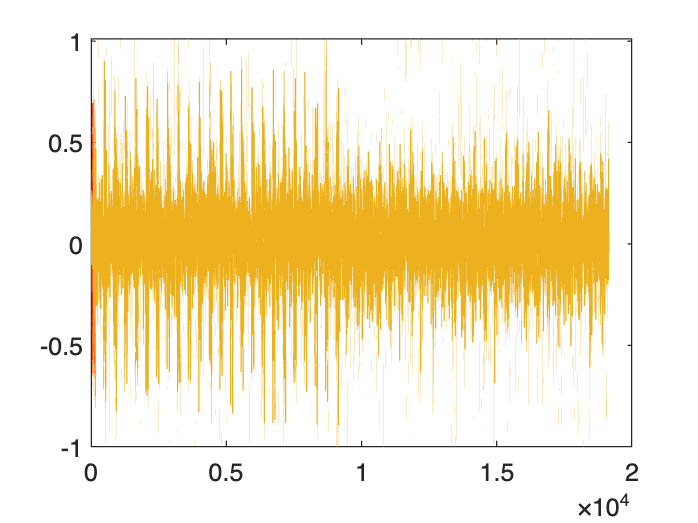

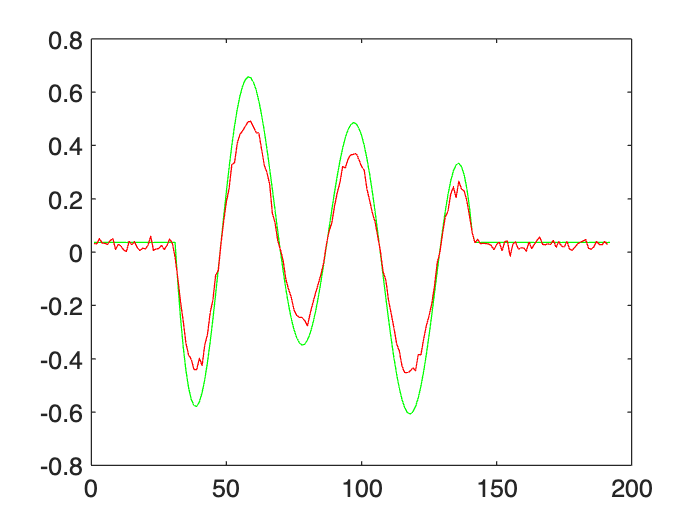

[s_a_tot, c_avg_tot] = correllated_average(e_p, trigger, ie_p);